%Problem 1
% Given filenames and alpha value
filenames = {'piano2.wav', 'trumpet2.wav', 'violin2.wav', 'flute2.wav'};

fundamental_frequencies = [];

for i = 1:length(filenames)
    filename = filenames{i};
    [signal, sample_rate] = audioread(filename);
    fft_result = fft(signal);
    magnitude_spectrum = db(fft_result);
    [~,peak_index] = max(magnitude_spectrum);
    num_samples = length(signal);
    freq_values = (0:num_samples-1)* (sample_rate/num_samples);
    fundamental_frequency = freq_values(peak_index);
    fundamental_frequencies = [fundamental_frequencies, fundamental_frequency];
    figure;
    plot(freq_values, magnitude_spectrum);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    title(['Magnitude Spectrum of ', filename]);
    grid on;
    
end



% Display the fundamental frequencies
disp('Instrument        Fundamental Frequency (Hz)');

Instrument        Fundamental Frequency (Hz)


for i = 1:length(filenames)
    [~, instrument_name, ~] = fileparts(filenames{i});
    fprintf('%-16s%.2f Hz\n', instrument_name, fundamental_frequencies(i));
end

piano2          523.62 Hz
trumpet2        1047.21 Hz
violin2         2369.12 Hz
flute2          524.33 Hz



% Fundamental frequency of the piano
piano_index = find(strcmp(filenames, 'piano2.wav'));
piano_fundamental = fundamental_frequencies(piano_index);

flutefiles = {'flute1.wav','flute2.wav','flute3.wav','flute4.wav'}

flutefiles = 1×4 cell array
    {'flute1.wav'}    {'flute2.wav'}    {'flute3.wav'}    {'flute4.wav'}


flute_peak = [];
for i = 1:length(flutefiles)
    filename = flutefiles{i};
    [signal, sample_rate] = audioread(filename);
    fft_result = fft(signal);
    magnitude_spectrum = db(fft_result);
    [~,peak_index] = max(magnitude_spectrum);
    num_samples = length(signal);
    freq_values = (0:num_samples-1)* (sample_rate/num_samples);
    fundamental_frequency = freq_values(peak_index);
    flute_peak = [flute_peak, fundamental_frequency];  
end
flute_peak

flute_peak = 1.0e+03 *

    1.0632    0.5243    0.7935    0.5244


flute_peaks = flute_peak - piano_fundamental

flute_peaks =   539.5823    0.7161  269.8863    0.7823


[~,max_flute_index] = min(flute_peaks)

max_flute_index = 2

req_flute = flutefiles(max_flute_index)

req_flute = 1×1 cell array
    {'flute2.wav'}



%Problem 2
% Record a 3-second snippet of whistling
duration = 3;  % Duration in seconds
fs = 44100;    % Sampling frequency

recObj = audiorecorder(fs, 16, 1);
disp('Start whistling...');

Start whistling...


recordblocking(recObj, duration);
disp('End of recording.');

End of recording.


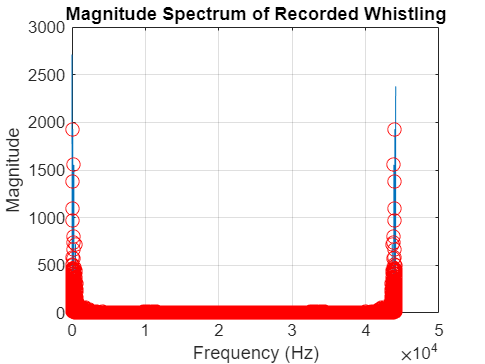


% Save the recorded audio as the reference
reference_audio = getaudiodata(recObj);
audiowrite('reference_whistle.wav', reference_audio, fs);

% Load the recorded whistling audio
[recorded_audio, fs_recorded] = audioread('reference_whistle.wav');

% Compute FFT of the recorded audio
fft_result = fft(recorded_audio);

% Calculate frequency bins
freq_bins = linspace(0, fs_recorded, length(fft_result));

% Calculate magnitude spectrum
magnitude_spectrum = abs(fft_result);

% Find peaks in the magnitude spectrum
[pks, peak_indices] = findpeaks(magnitude_spectrum);

% Plot the magnitude spectrum
figure;
plot(freq_bins, magnitude_spectrum);
hold on;
plot(freq_bins(peak_indices), pks, 'ro', 'MarkerSize', 8);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Magnitude Spectrum of Recorded Whistling');
grid on;


% Find the highest peak frequency
[~, max_peak_index] = max(pks);
fundamental_frequency_recorded = freq_bins(peak_indices(max_peak_index));

fprintf('Fundamental Frequency of Recorded Whistling: %.2f Hz\n', fundamental_frequency_recorded);

Fundamental Frequency of Recorded Whistling: 104.00 Hz



% Test case 1: 
checkAccess();

Unrecognized function or variable 'checkAccess'.


% Test case 2: 
checkAccess();

% Test case 3: 
checkAccess();



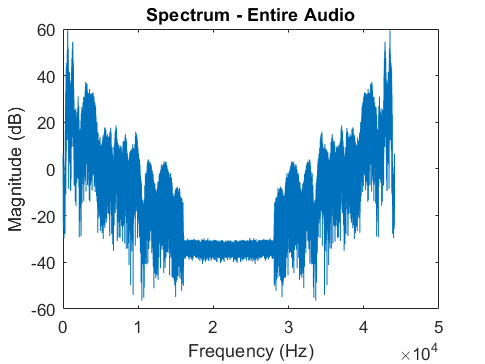


[y, fs] = audioread('Opera.wav');

segmentSize = 2000; % Number of samples per segment
numSegments = 11; % Total number of segments

overlap = 0; % No overlap between segments

stepSize = (segmentSize - overlap);
figureCounter = 1;
fullSpectrum = fft(y);
fFull = linspace(0, fs, length(fullSpectrum));

figure(figureCounter);
plot(fFull, 20 * log10(abs(fullSpectrum)));
title('Spectrum - Entire Audio');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

figureCounter = figureCounter + 1;

[x, fs] = audioread('Opera.wav');

windowSize = 1024;  % Size of the analysis window
overlap = 512;     % Overlap between consecutive windows
nfft = 1024;        % Number of FFT points
[S, F, T] = spectrogram(x, windowSize, overlap, nfft, fs);

S_dB = 10 * log10(abs(S));

figure;
imagesc(T, F, S_dB);  % Display the spectrogram
axis xy;              % Invert the y-axis to have lower frequencies at the bottom
colormap jet;        % Set the colormap (you can choose different colormaps)
colorbar;            % Add a colorbar to the plot
title('Spectrogram of Opera.wav');
xlabel('Time (s)');
ylabel('Frequency (Hz)');

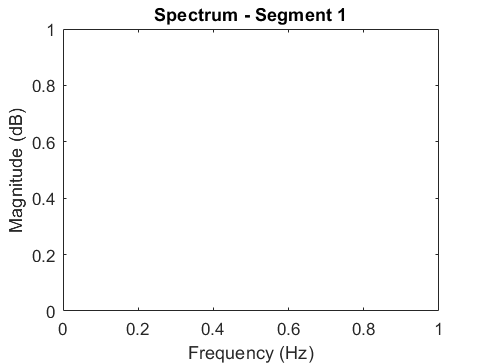

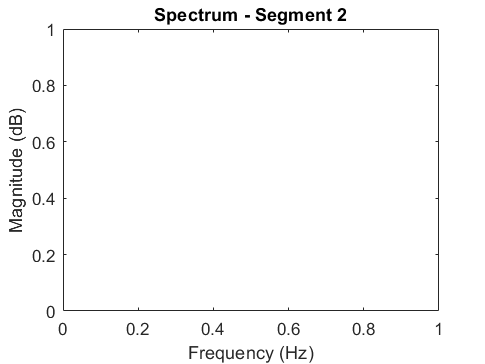

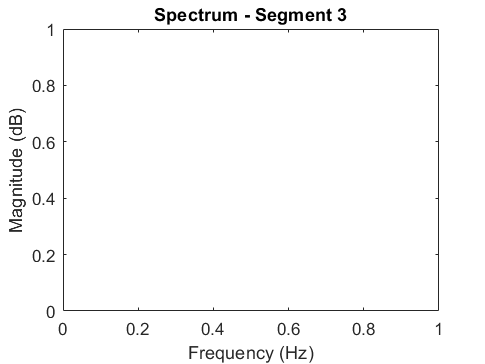

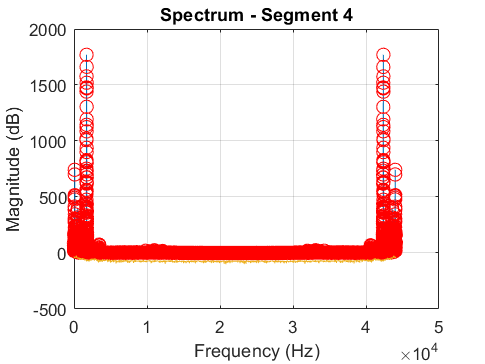

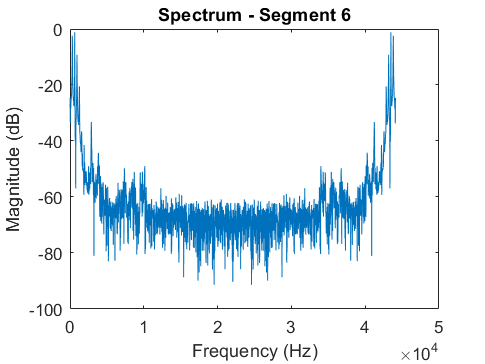

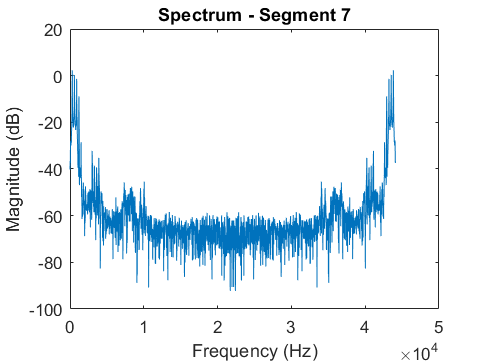

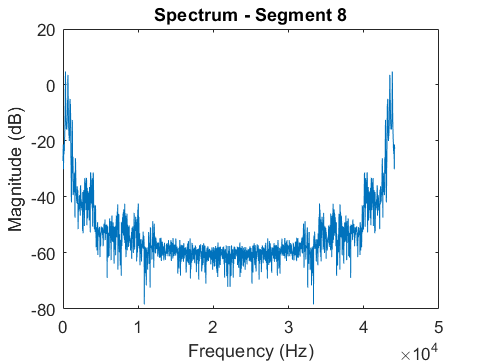

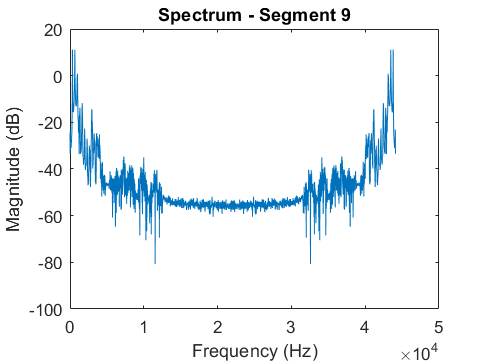


for i = 1:numSegments
    startIdx = (i - 1) * stepSize + 1;
    endIdx = startIdx + segmentSize - 1;

    segment = y(startIdx:endIdx);
    spectrum = fft(segment);
    f = linspace(0, fs, segmentSize);

    figure(figureCounter);
    plot(f, 20 * log10(abs(spectrum)));
    title(['Spectrum - Segment ', num2str(i)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude (dB)');
    figureCounter = figureCounter + 1;
end